assert(endsWith(pwd, "non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [6e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 20; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D(r,z);

calculate geometry took 0.00 seconds


clear disk r z

Model.conductivity = 3.774e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 29.60 seconds


#### Solve in time domain

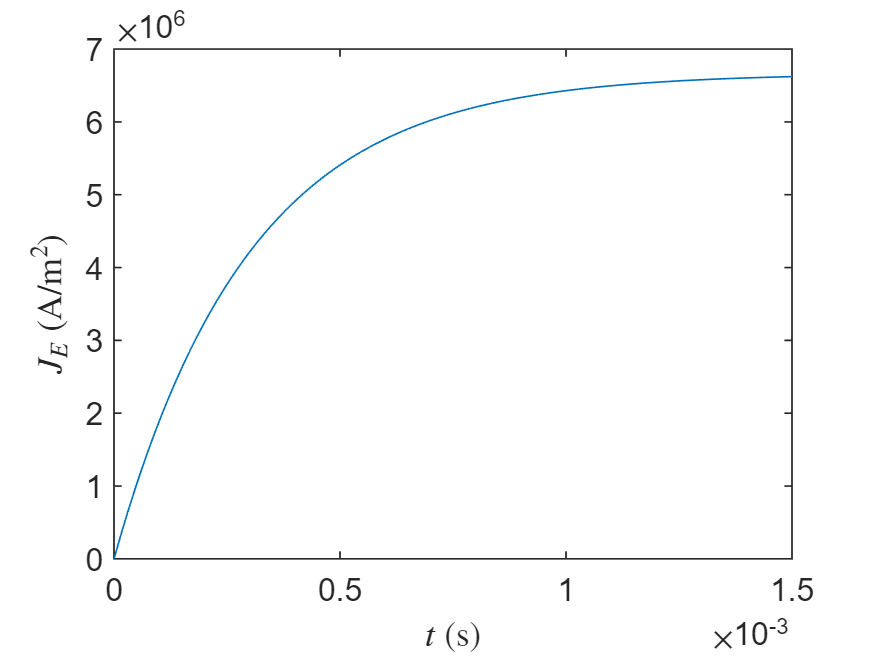

I_E_ss = 1; % (A)
J_E_ss = I_E_ss * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
tau = 3e-4; % (s)

EM.time_domain.current_density = @(t) J_E_ss * (1 - exp(-t/tau));
EM.time_domain.current_density_diff = @(t) J_E_ss/tau * exp(-t/tau);
% EM.time_domain.current_density_diff2 = @(t) -J_E_ss/tau^2 * exp(-t/tau);
EM.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(EM.time_domain.time_span(1), EM.time_domain.time_span(end));
plot(t, EM.time_domain.current_density(t))
ylabel('$J_E$ (A/m$^2$)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss J_E_ss tau t

[Model, EM, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, EM, Sensor);

solve J   took 0.19 seconds
solve B_E took 0.10 seconds
solve B_C took 0.19 seconds


#### Plot result

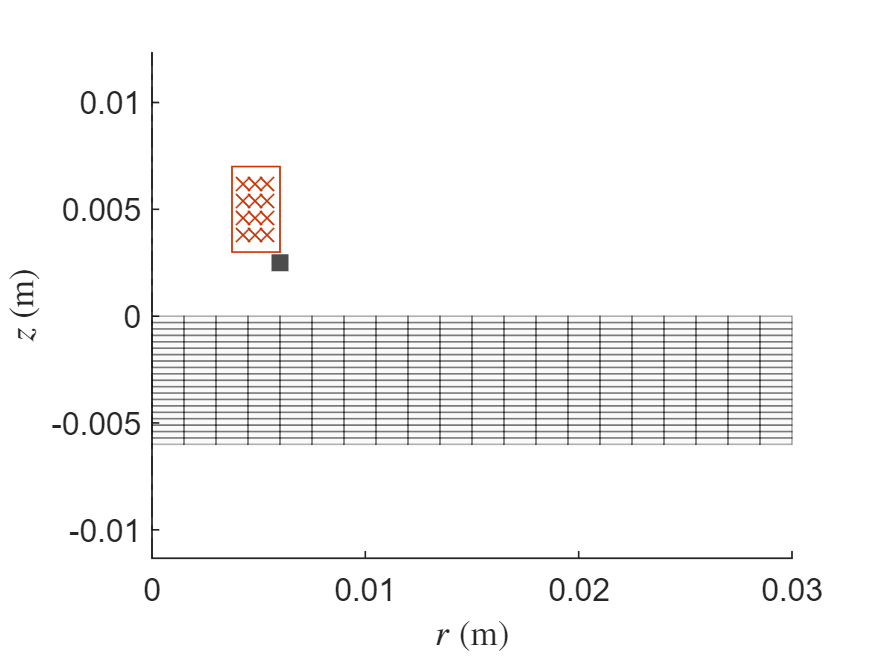

PlotWorld2D(Model, EM, Sensor);

clf

## Compare with FEA

#### Magnetic flux density

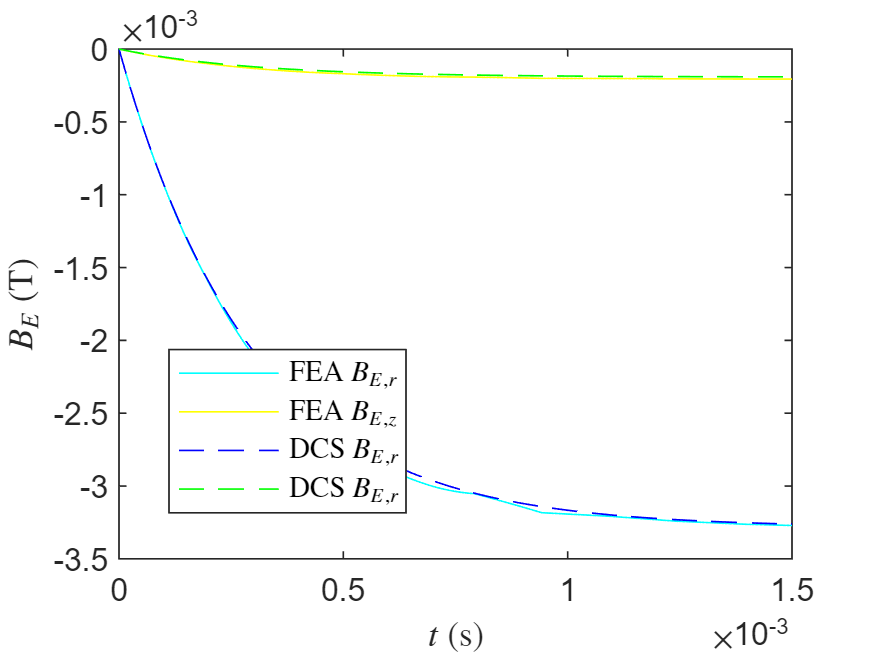

data = readmatrix('FEA_data\B_E.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.t = data(1,:);
FEA.B_E_r = data(2,:);
FEA.B_E_z = data(3,:);
data = readmatrix('FEA_data\B_E_plus_B_C.csv', 'CommentStyle','%');
data = reshape(data(3:end), 3, []);
FEA.B_C_r = data(2,:) - FEA.B_E_r;
FEA.B_C_z = data(3,:) - FEA.B_E_z;

plot(FEA.t, FEA.B_E_r, 'c-', 'DisplayName','FEA $B_{E,r}$'); hold on
plot(FEA.t, FEA.B_E_z, 'y-', 'DisplayName','FEA $B_{E,z}$');
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(1,1,:)), 'b--', 'DisplayName','DCS $B_{E,r}$');
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'g--', 'DisplayName','DCS $B_{E,r}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

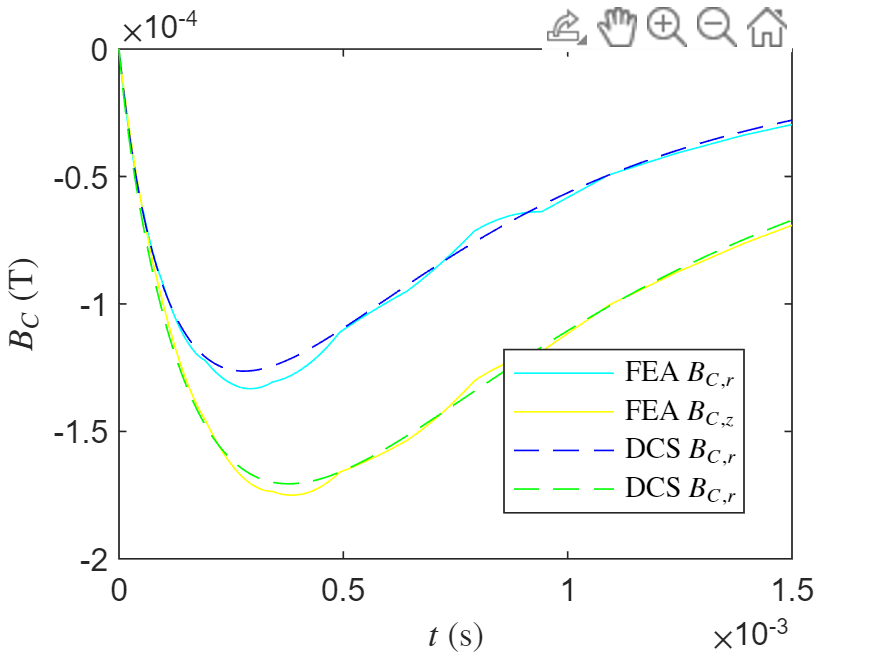

clf

plot(FEA.t, FEA.B_C_r, 'c-', 'DisplayName','FEA $B_{C,r}$'); hold on
plot(FEA.t, FEA.B_C_z, 'y-', 'DisplayName','FEA $B_{C,z}$');
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(1,1,:)), 'b--', 'DisplayName','DCS $B_{C,r}$');
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'g--', 'DisplayName','DCS $B_{C,r}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

FEA_B_C = interp1(FEA.t, FEA.B_C_r, Sensor.time_domain.t);
DCS_B_C = squeeze(Sensor.time_domain.B_C(1,1,:));
[error, i] = maxk(abs(DCS_B_C - FEA_B_C), 100);
fprintf('B_C_r average relative error %e\n', mean(error ./ abs(FEA_B_C(i))));

B_C_r average relative error 5.184824e-02


FEA_B_C = interp1(FEA.t, FEA.B_C_z, Sensor.time_domain.t);
DCS_B_C = squeeze(Sensor.time_domain.B_C(2,1,:));
[error, i] = maxk(abs(DCS_B_C - FEA_B_C), 100);
fprintf('B_C_z average relative error %e\n', mean(error ./ abs(FEA_B_C(i))));

B_C_z average relative error 5.909344e-02



clear data FEA_B_C DCS_B_C error i